# Theoretical exploration of logistic curve of N effect on A

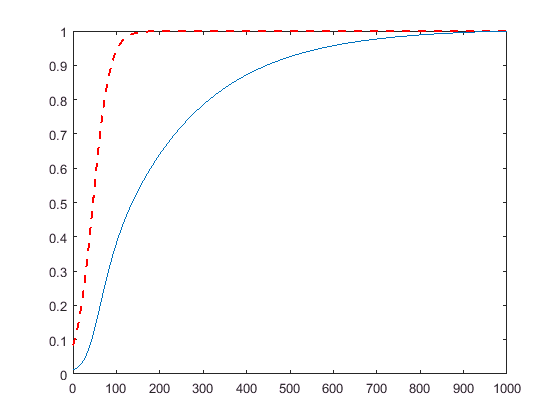

Nfunc = @(N0,Ns,a,t) Ns./(1+((Ns./N0)-1).*exp(-a.*t));
N0=1;
Ns=12;
t = 0:3:1000;
N = Nfunc(N0,Ns,0.052,t);
figure
p3 = plot(t,N./max(N),'--r','LineWidth',1.5);

% Afunc = @(N) 0.08.*N;
% hold on
% A = Afunc(N);
% 
% plot(t,A./max(A))
Afunc = @(N,A0,d,g,t) (A0-g.*N).*exp(-d.*t./g)+g.*N;
%Am = Afunc(N,30,3.054,5.574,t);
Am = Afunc(N,0.15,0.005,1,t);

hold on
plot(t,Am./max(Am))

**Conclusion: model in Rasse and Deneubourg (2001) not effective for growing population, lag between pop growth and area not apparent in model as appears in mean and specific experiments results**

**To create lag, need very low dig rate per ant, around 0.005 sq.cm/ant/day => does not make sense?!?!?**

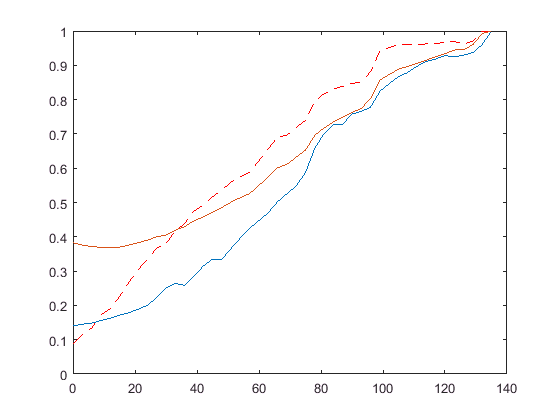

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(1).Mean(t0:tend);
Aer = M(1).SEM(t0:tend);
N = M(13).Mean(t0:tend);
Ner = M(13).SEM(t0:tend);

figure; plot(t1,N./max(N),'--r',t1,A./max(A))
hold on
Am = Afunc(N,20,0.05,5.574,t1);
plot(t1,Am./max(Am))

plugged in real N data did not change anything, no lag

TRY logistic area model based on N

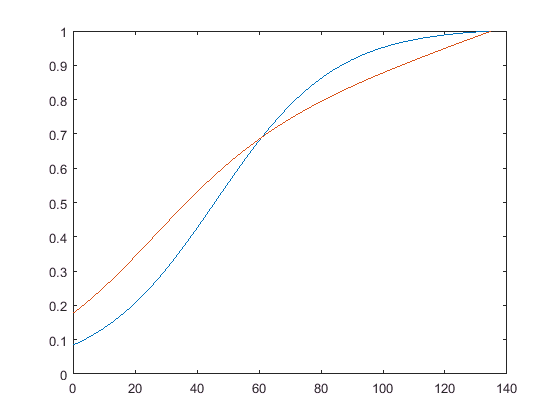

t = 0:3:135;
N0=1;
Ns=12;
N = Nfunc(N0,Ns,0.052,t);
Afunc2 = @(N,A0,d,g,t) (g.*N)./(1+(g.*N./A0).*exp(-d.*t));
Am2 = Afunc2(N,20,0.005,5.574,t);


figure
plot(t,N./max(N),t,Am2./max(Am2))

## New integral feedback model for digging rate as function of deviation from area per ant steady state value

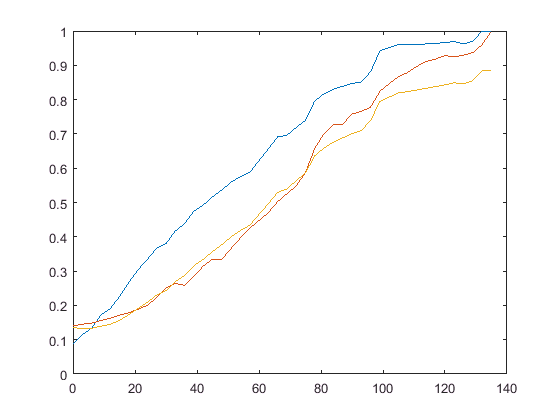

Afunc3 = @(N,A0,sAst,r,t) (A0-N.*sAst).*exp(-r.*t./sAst)+N.*sAst;
Am3 = Afunc3(N,20,11.5,0.27,t1);
figure
plot(t1,N./max(N),t1,A./max(A),t1,Am3./max(A))

Gety general trend back and can use it